IF = 2e6;
fs = 10.23e6;
t_coh = 0.001;
cnt = 4000;
code_freq = 1.023e6;
ipr = zeros(1, cnt);
ier = zeros(1, cnt);
ilr = zeros(1, cnt);
codel = 0;
codes = 0.5;
phasetl = 0;
% er = zeros(1, cnt);
doppler_freq_increase = 0.01;                % how much doppler freq increase per t_coh
df = 0;
%------------------      FLL,PLL and DLL settings     --------------------% 
FLL_i_sum = 0;
PLL_i_sum = 0;
FLL_o = zeros(1, cnt);
PLL_o = zeros(1, cnt);
DLL_o = zeros(1, cnt);
FLL_BandWidth = 6;
PLL_BandWidth = 6;
DLL_BandWidth = 2;
FLL_i = zeros(1, 2);
PLL_i = zeros(1, 2);
DLL_i = zeros(1, 2);
DLL_r = zeros(1, cnt);
FLL_r = zeros(1, cnt);

wnf = 1.89 * FLL_BandWidth;
wnp = 1.275 * PLL_BandWidth;
wnd = 1.89 * DLL_BandWidth;
a2 = sqrt(2);
a3 = 1.1;
b3 = 2.4;
%-------------------------------------------------------------------------%

%------------------      parameters to generate simulate signal     --------------------%    
doppler_freq = 100;
SNR = -20;
var_n = 1;
noise_Amp = 1;
signal_Amp = sqrt(var_n*10^(SNR/10));
prn = 32;
%---------------------------------------------------------------------------------------% 



tt = 1/fs:1/fs:t_coh;
carrier_freq = zeros(1, t_coh * fs);
sp = t_coh * fs;                             % sample points in a t_coh period
x = doppler_freq_increase/sp:doppler_freq_increase/sp:doppler_freq_increase;
weil = weil_code_generator(prn);             % generate weil code
for i = 1:cnt
%------------------      generate simulating signal     --------------------%    
    doppler_freq = df + x;
    carrier_freq = IF + doppler_freq;
    df = doppler_freq(end);
    t = (i - 1) * t_coh + 1/fs:1/fs:i*t_coh;
    carrier = signal_Amp * cos(2 * pi * carrier_freq .* t) + sqrt(var_n) * randn(1, t_coh*fs);
    code_f = code_freq + doppler_freq;
    tf_sim = tt .* code_f + codes;
    codes = tf_sim(end);
    tf_sim = mod(floor(tf_sim), 10230) + 1;
    weil_sim = weil(tf_sim);
    signal_sim = carrier .* weil_sim;
    if i == 1
%------------------      generate local cos/sin signal and EPL code     --------------------%
        cos_t = cos(2 * pi * (IF) * t);
        sin_t = -sin(2 * pi * (IF) * t);
        phasetl = (IF) * t(end);
        tf = tt * code_freq + codel;
        tfl = (tt - 5/fs) * code_freq + codel;
        tfe = (tt + 5/fs) * code_freq + codel;
        codel = tf(end);
        tf = mod(floor(tf), 10230) + 1;
        tfl = mod(floor(tfl), 10230) + 1;
        tfe = mod(floor(tfe), 10230) + 1;
        weil_prompt = weil(tf);
        weil_late = weil(tfl);
        weil_early = weil(tfe);
    else
        phaset = phasetl + tt* (IF + FLL_o(i - 1) + PLL_o(i - 1)/(2*pi));
        phasetl = phaset(end);
        cos_t = cos(2 * pi * phaset);
        sin_t = -sin(2 * pi * phaset);
        
        tf = tt * (code_freq + DLL_o(i - 1) + FLL_o(i - 1)/1540) + codel;
        tfl = (tt - 5/fs) * (code_freq + DLL_o(i - 1) + FLL_o(i - 1)/1540) + codel;
        tfe = (tt + 5/fs) * (code_freq + DLL_o(i - 1) + FLL_o(i - 1)/1540)  + codel;
        codel = tf(end);
        tf = mod(floor(tf), 10230) + 1;
        tfl = mod(floor(tfl), 10230) + 1;
        tfe = mod(floor(tfe), 10230) + 1;
        weil_prompt = weil(tf);
        weil_late = weil(tfl);
        weil_early = weil(tfe);
    end
    signal_i = signal_sim.*cos_t;
    signal_q = signal_sim.*sin_t;
    [ie, ip, il, qe, qp, ql] = tracking_correlator(signal_i, signal_q, weil_early, weil_prompt, weil_late);
    E = sqrt(ie^2 + qe^2);
    L = sqrt(il^2 + ql^2);    
    

    ipr(i) = ip;
    ilr(i) = il;
    ier(i) = ie;
%     er(i) = sum(abs(weil_sim - weil_prompt));
    if i ~= 1
        p_cross = ipl*qp - ip*qpl;
        p_dot = ipl*ip + qpl*qp;
%------------------      FLL     --------------------%
        FLL_i(1) = FLL_i(2);
        % F-discriminator
        FLL_i(2) =  atan2(p_cross, p_dot)/(t_coh * 2*pi);
        FLL_i_sum = FLL_i_sum + FLL_i(2);
        % filter
        FLL_o(i) = FLL_o(i - 1) + 2*wnf^2*t_coh^2*FLL_i_sum + (a2*wnf*t_coh - 3/2*wnf^2*t_coh^2)*FLL_i(2) - (wnf^2*t_coh^2/2-a2*wnf*t_coh)*FLL_i(1);
        FLL_r(i) = FLL_i(2);
%------------------      PLL     --------------------%        
        PLL_i(1) = PLL_i(2);
        % P-discriminator
        PLL_i(2) = atan2(qp, ip);
        PLL_i_sum = PLL_i_sum + PLL_i(2);
        % filter
        PLL_o(i) = PLL_o(i - 1) + 2*wnp^3*t_coh^2*PLL_i_sum + (a3*wnp^2*t_coh - 3/2*t_coh^2*wnp^3 + b3*wnp)*PLL_i(2) - (t_coh^2*wnp^3/2 - a3*wnp^2*t_coh + b3*wnp)*PLL_i(1);
%------------------     DLL     --------------------%
        DLL_i(1) = DLL_i(2);
        % discriminator
%         DLL_i(2) = (E^2 - L^2) / (E^2+L^2) /2;
        DLL_i(2) = ((ie - il)*ip + (qe - ql)*qp)/(ip^2+qp^2)/2;
%         DLL_i(2) = (E - L) / (E + L) / 2;
        % filter
        DLL_o(i) = DLL_o(i - 1) + (wnd^2*t_coh/2 + a2*wnd)*DLL_i(2) - (a2*wnd-wnd^2*t_coh/2)*DLL_i(1);
%         DLL_o(i) = 0.95 * DLL_o(i - 1) + 0.05 * DLL_i(2);
        DLL_r(i) = DLL_i(2);
    end
    ipl = ip;
    qpl = qp; 
end

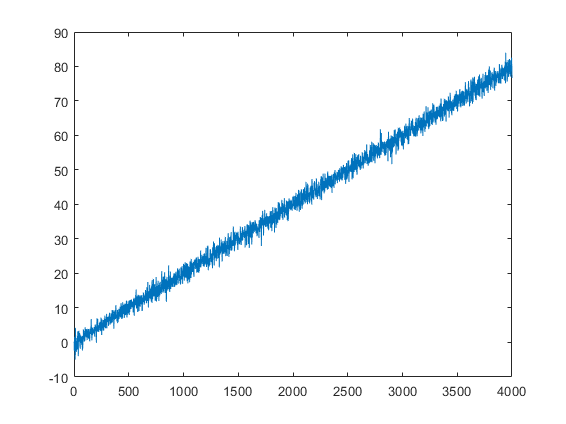

figure;
plot(PLL_o/(2*pi)+FLL_o);

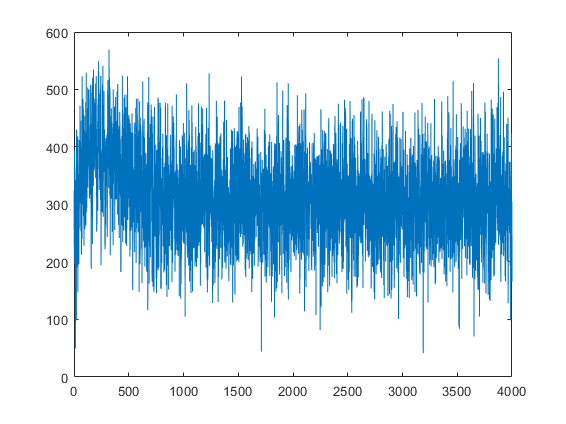

% plot(DLL_o);
plot(ipr);

% hold on;
% plot(ilr(1:20));
% plot(ier(1:20));
% hold off;
% plot(FLL_r);
% plot(er);.